clear all;
clc;
close all;
disp('Iris Eting 209027333')

Iris Eting 209027333


disp('Nadav Orenstein 312349509')

Nadav Orenstein 312349509


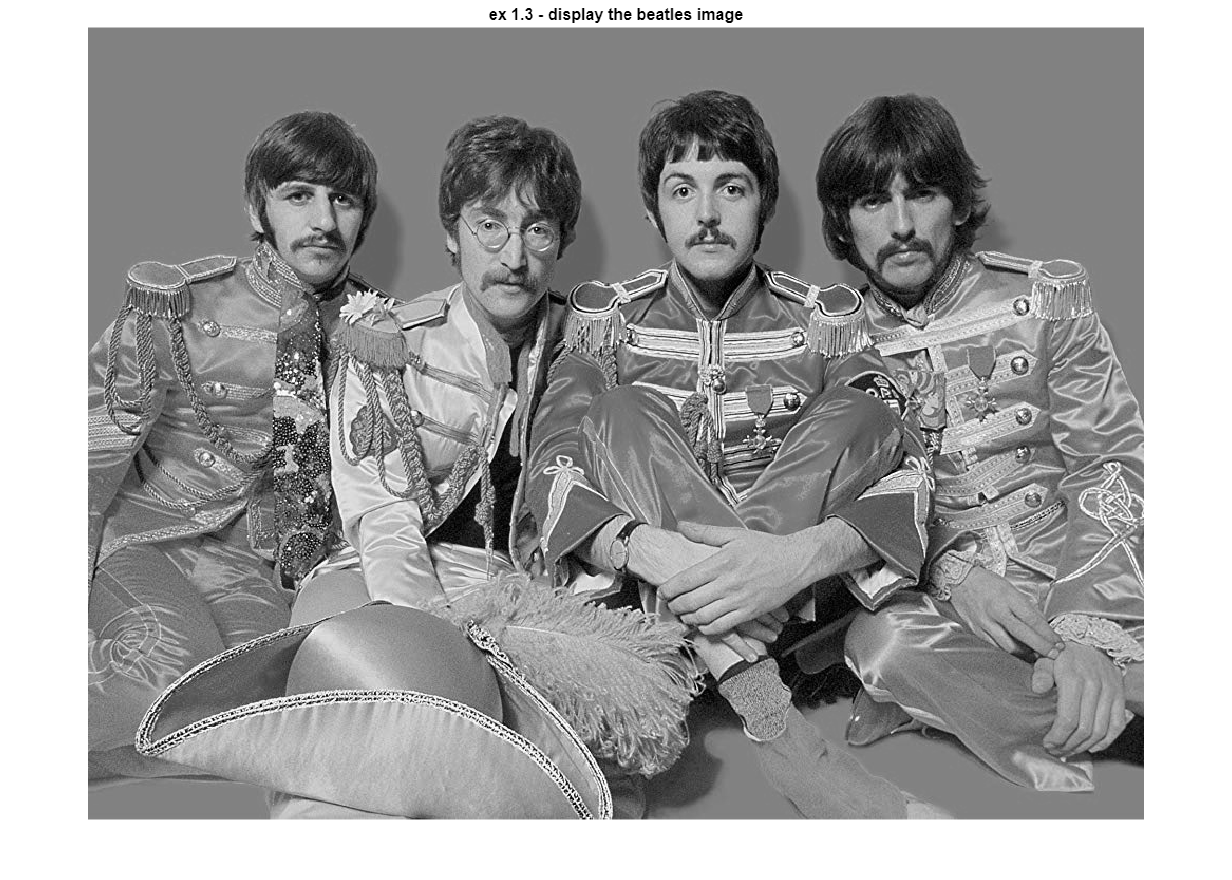

%%% 1.1 -1.2 are in the added functions.
%%% 1.3

beatles = imread_normalized("beatles.png");

fig = figure();                                                 % plotting the image
imshow(beatles);
title('ex 1.3 - display the beatles image');
saveas(fig,'ex 1.3.jpeg')

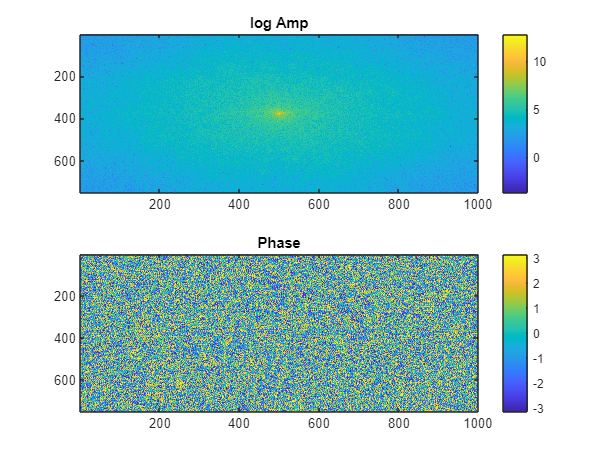

%%% 1.4
F = dip_fft2(beatles);
F_shift = dip_fftshift(F);
figure();
subplot(2,1,1);imagesc(log(abs(F_shift)));colorbar;title('log Amp');
subplot(2,1,2);imagesc(angle(F_shift));colorbar;title('Phase');

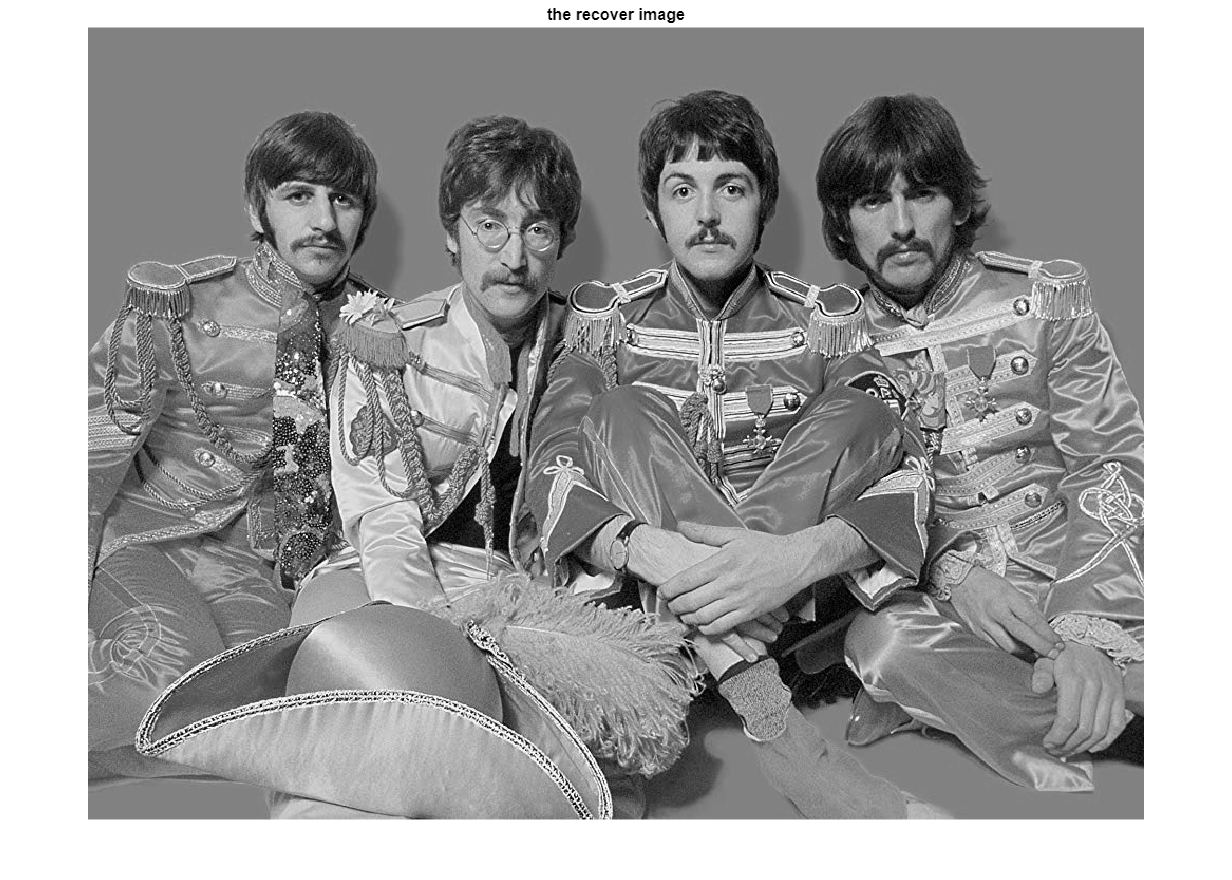

%%% 1.5 
beatles_rec = dip_ifft2(F);
figure(); imshow(real(beatles_rec));title('the recover image')

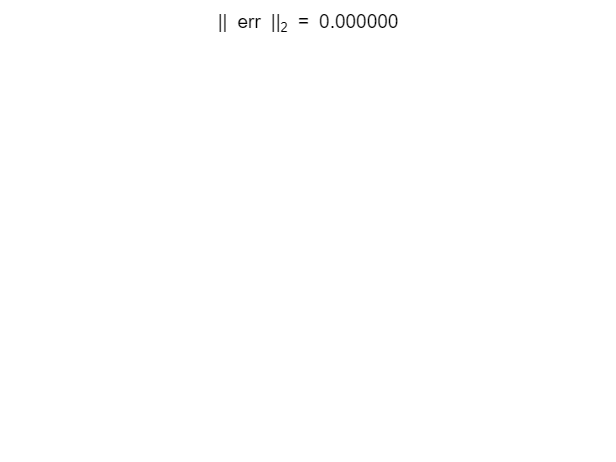

L2_err = norm(abs(real(beatles_rec)-beatles), 2);

fig = figure();
formated = sprintf('|| err ||_2 = %f', L2_err);
sgtitle(formated);

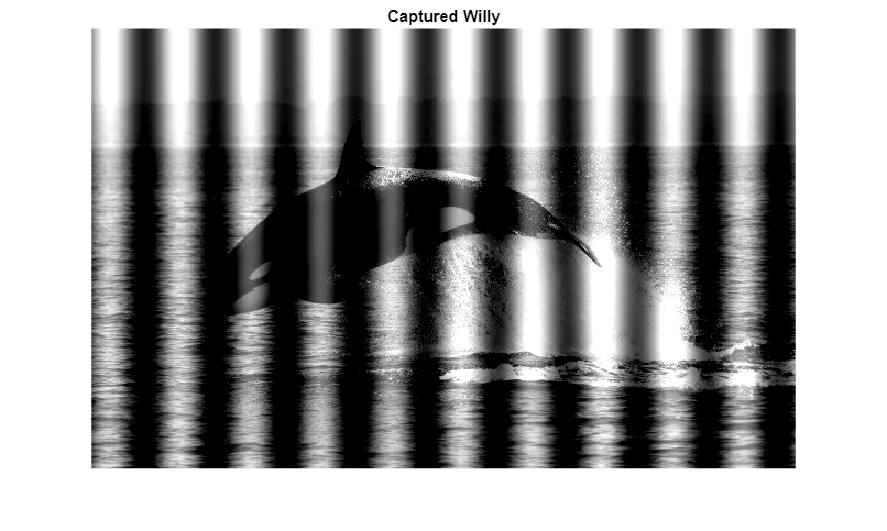

clear all;
clc;
close all;
%%%%%%%%%%%%% 1.2 Transformation properties %%%%%%%%%%%%%%%%%%%%
%%% 1. Linearity (Free Willy)
load("freewilly.mat");
imshow(freewilly)
title('Captured Willy');

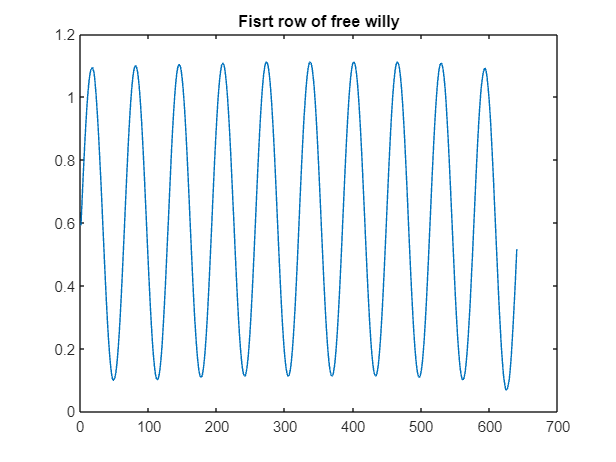


figure; plot(freewilly(1,:));
title('Fisrt row of free willy');


fx = size(findpeaks(freewilly(1,:)),2)

fx = 10

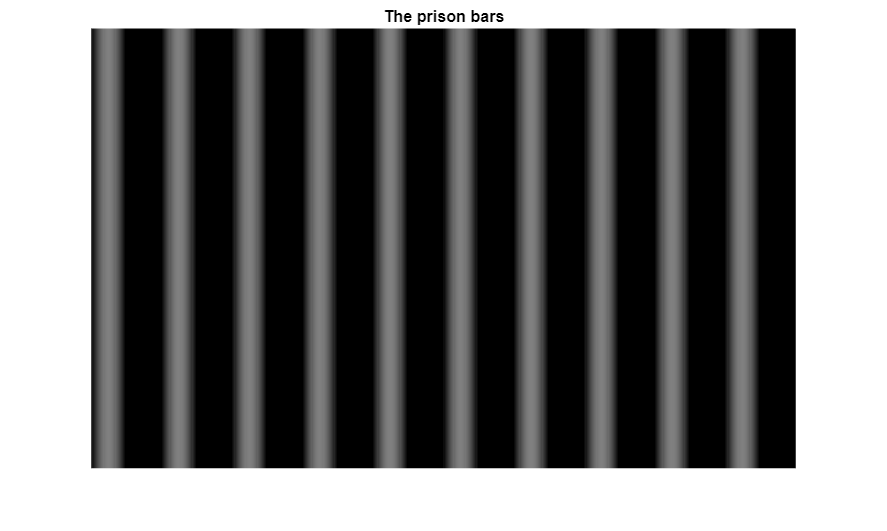



%% plot the prison
M = size(freewilly, 1);
N = size(freewilly, 2);
x = 1:N;
prison = 0.5 .* sin(2*pi*fx.*x./N);
P = ones(M,N).*prison;
figure();imshow(P);title('The prison bars');

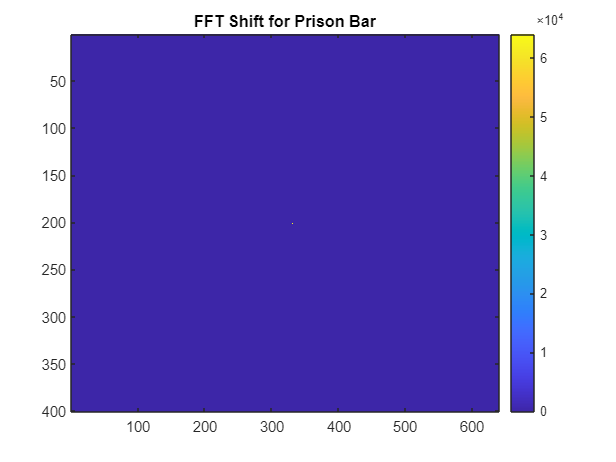


%% FFT for the prison bars
prison_ffts = fftshift(fft2(P));
figure; imagesc(abs(prison_ffts));
title('FFT Shift for Prison Bar')
colorbar;

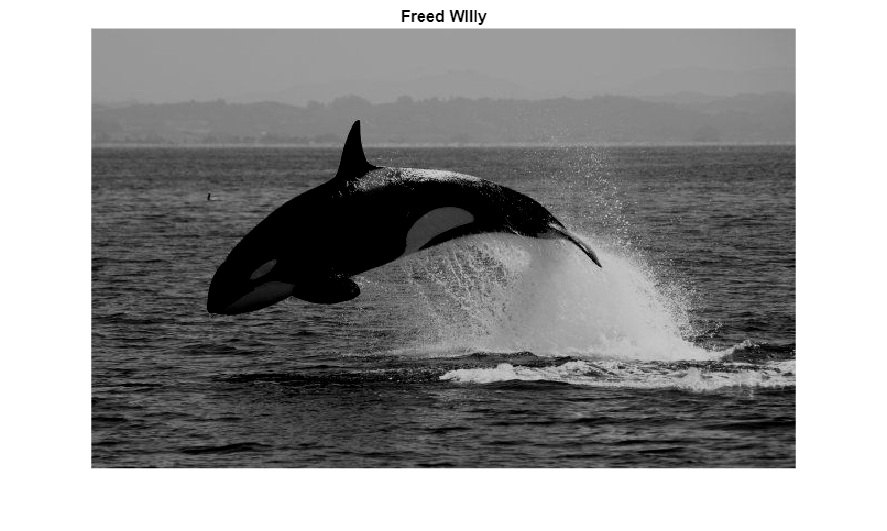


% free willy
free_willy = Free_Willy(freewilly);

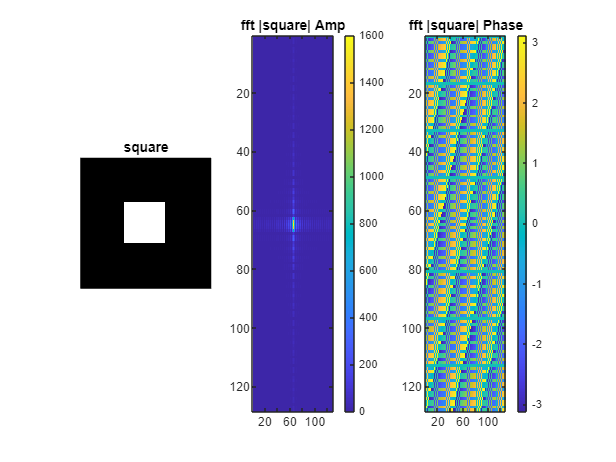

%%%% 2. Scaling, translation and seperability
%We initialize a 128×128 all-zeros matrix. At the center of it, we placed a 40×40 all-ones square (in pixels 44:83 in each dimension). We display the image and its 2D-FFT:
A = zeros(128,128);

A(44:83,44:83) = 1;
fft_mat_shift = fftshift(fft2(A));

figure;
subplot(1,3,1);
imshow(A);
title('square');

subplot(1,3,2);
imagesc(abs(fft_mat_shift));
title('fft |square| Amp');
colorbar;
subplot(1,3,3);
imagesc(angle(fft_mat_shift));title('fft |square| Phase');colorbar;

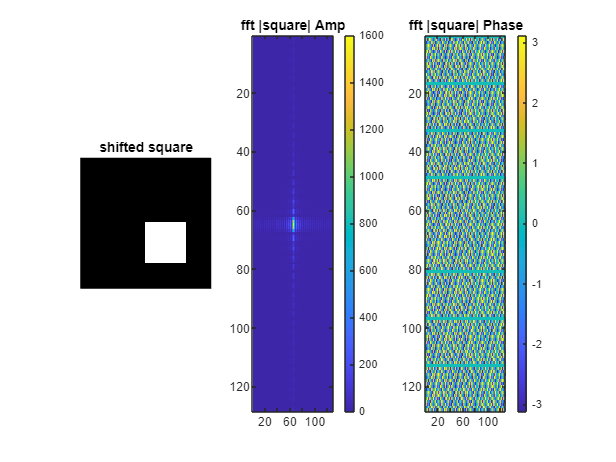

%% 2.b.

%init the matrix
B = zeros(128,128);

%generate the rectangle shape
B(64:103,64:103) = 1;
fft_mat_shift_B = fftshift(fft2(B));

%show the shape
figure;
subplot(1,3,1);
imshow(B);
title('shifted square');
%show the amp
subplot(1,3,2);
imagesc(abs(fft_mat_shift_B));

%show the phase
title('fft |square| Amp');colorbar;
subplot(1,3,3);
imagesc(angle(fft_mat_shift_B));title('fft |square| Phase');colorbar;

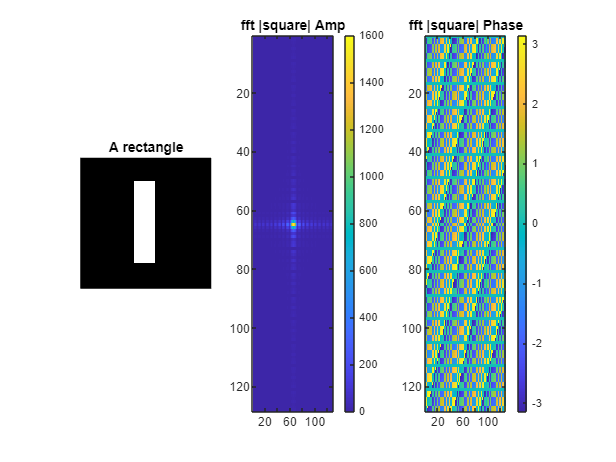

%init the matrix
C = zeros(128,128);

%generate the rectangle shape
C(24:103,54:73) = 1;
fft_mat_shift_C = fftshift(fft2(C));

%show the shape
figure;
subplot(1,3,1);
imshow(C);
title('A rectangle');

%show the amp
subplot(1,3,2);
imagesc(abs(fft_mat_shift_C));

%show the phase
title('fft |square| Amp');colorbar;
subplot(1,3,3);
imagesc(angle(fft_mat_shift_C));title('fft |square| Phase');colorbar;

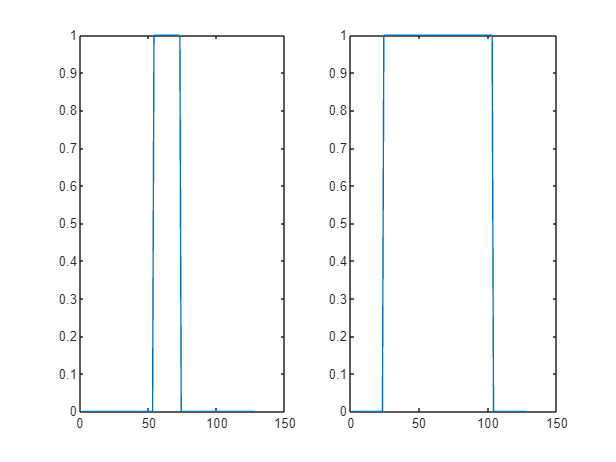


%e 
xn = C(64,:);
figure;
subplot(1,2,1);
plot(xn);

%show the amp
xm=C(:,64);
subplot(1,2,2);
plot(xm);

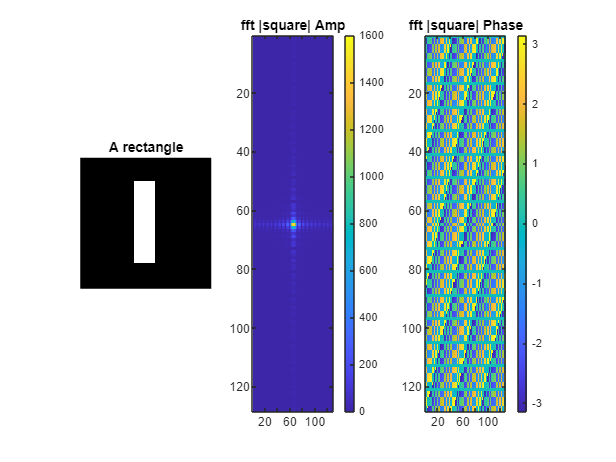

sep_F = fftshift(sep_fft2(xm,xn));
%show the shape
figure;
subplot(1,3,1);
imshow(C);
title('A rectangle');

%show the amp
subplot(1,3,2);
imagesc(abs(sep_F));

%show the phase
title('fft |square| Amp');colorbar;
subplot(1,3,3);
imagesc(angle(sep_F));title('fft |square| Phase');colorbar;